# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

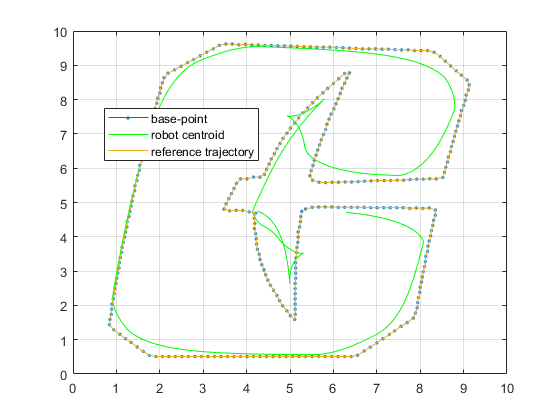

clear all
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter

global D h k;
%       position = importdata("trajectory.mat");
%       D =10; k =10; h = .02;
%       position = flip(position);
% position = importdata("CharlotteLogo.mat");
D =.05; k =10; h = 0.02;

down_sample_amount = 15;

  position = importdata("position_Array.mat");
  down_sample_amount = 1;


% position = importdata("CharlotteLogo.mat");
% D =1; k =10; h = .02;
% position  = position'/100;


  l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
  state(:,1) = [position(1,1)-D; position(2,1); 0];

  xb(1) = state(1,1) + D*cos(state(3,1));
  yb(1) = state(2,1) + D*sin(state(3,1));
  theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;
velocity = [xVelocity; yVelocity];
for i= 1:T
reference_velocity(i) = norm(velocity(:,i));
end 

for t =1 : T

    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
     
     linear_vel(t) = v;
     angular_vel(t) = w;
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w);
    
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [v*cos( state(3,t)); v*sin(state(3,t)); w]; 
    
end

% xk(1,:) = xb;
% xk(2,:) = yb;
% xk(3,:) = theta;
% save("UNCCLOGO_Centroid","state")
% save("charlotte_position","position")
% save("pdrcircle","xk")
% save("charlotte_centroid.mat","state")

figure
plot(xb, yb, '.-')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
grid on;
legend('base-point', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

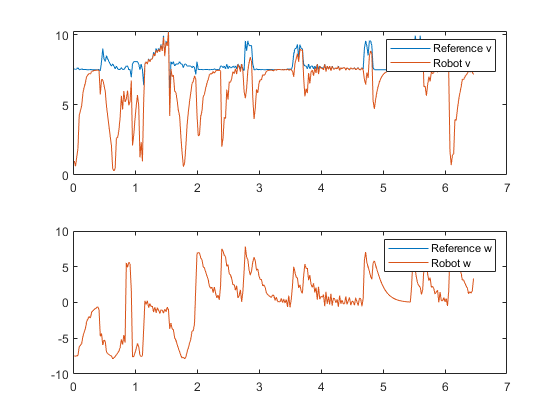


figure
subplot(2,1,1)
plot([1:size(linear_vel,2)]*h, reference_velocity);
hold on
plot([1:size(linear_vel,2)]*h, abs(linear_vel));
legend('Reference v', 'Robot v')
hold off
subplot(2,1,2)
plot([1:size(angular_vel,2)]*h, angular_vel);
hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('Reference w', 'Robot w')
hold off

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v; w];

end